value_table = [0 2 4 6 8 10;
               -10 20 0 30 40 40;
               0 10 -10 10 0 0];
coef_table = zeros(size(value_table,2)-1,4);
for i = 1:size(value_table,2)-1
    h = value_table(1,i+1) - value_table(1,i);
    coef_mat = [1 0 0 0;
                1 h h^2 h^3;
                0 1 0 0;
                0 1 2*h 3*h^2];
    value_vec = [value_table(2,i) value_table(2,i+1) value_table(3,i) value_table(3,i+1)].';
    coef_table(i,:) = (coef_mat\value_vec).';
end
coef_table

coef_table =   -10.0000         0   17.5000   -5.0000
   20.0000   10.0000  -20.0000    5.0000
         0  -10.0000   27.5000   -7.5000
   30.0000   10.0000   -2.5000         0
   40.0000         0         0         0


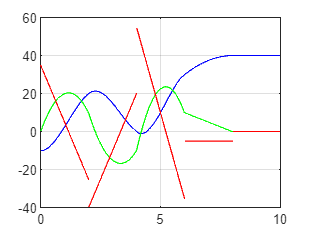

for i = 1:size(value_table,2)-1
    x = linspace(value_table(1,i+1),value_table(1,i));
    tk = value_table(1,i);
    ak = coef_table(i,1);
    bk = coef_table(i,2);
    ck = coef_table(i,3);
    dk = coef_table(i,4);
    y1 = ak + bk * (x - tk) + ck * (x - tk).^2 + dk * (x - tk).^3;
    y2 = bk + 2 * ck * (x - tk) + 3 * dk * (x - tk).^2;
    y3 = 2 * ck + 6 * dk * (x - tk);
    plot(x,y1,'b',x,y2,'g',x,y3,'r');
    hold on;
end
grid on;
hold off;